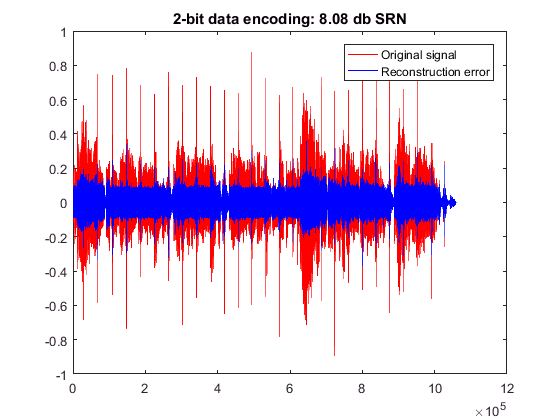

close all;
clear all;

%% Wczytanie sygnału
[x, fs] = audioread('DontWorryBeHappy.wav');
x = double( x );
x = x(:, 1); % przetwarzamy lewy kanal

%% Okno analizy i syntezy
N = 32; % dlugosc okna w probkach
n = 1:N;
h = sin(pi*(n+0.5)/N); % okno analizy i syntezy

%% Macierz analizy
A = zeros(N/2, N); % wymiar macierzy MDCT (z polecenia w pdf)
for k = 1:N/2   % tworzenie tej macierzy
    A(k, :) = sqrt(4/N)*cos(2*pi/N*(k-1+0.5)*(n+0.5+N/4));
end
%% Macierz syntezy
S = A';


Q = 2;
y = zeros(1, length(x));
dref = y;
for i=1:N/2:length(x)-N
    sample = x(i:i+N-1);
    windowed = sample'.*h;
    matrixed = A*windowed';
    
    quantized = round(matrixed*Q);
    dematrixed = S*quantized;
    dewindowed = h.*dematrixed';
    y(i:i+N-1) = y(i:i+N-1) + dewindowed;
    
    dematrixed = S*matrixed;
    dewindowed = h.*dematrixed';
    dref(i:i+N-1) = dref(i:i+N-1) + dewindowed;
end

y = y/Q;

n=1:length(x);
figure;
plot( n, x, 'r', n, y, 'b');
title('Sygnał oryginalny vs po odkodowaniu z MDCT');
legend('Sygnal oryginalny', 'Sygnal zrekonstr.')

%sound(y, fs)